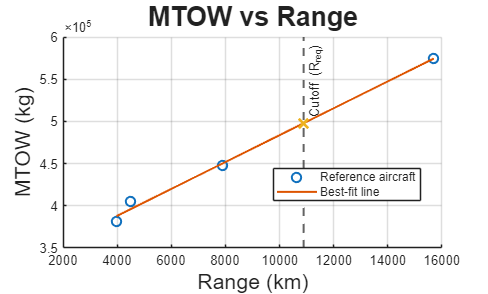

% Best-fit line (linear regression) + cutoff at required range
% Order: [747-8F, A380-800, An-124-100, C-5M, 787-10]

R = [7900 15700 4500 3980 ];          % Range (km)
W = [447700 575000 405000 381000 ];  % MTOW (kg)
DoStop = true;
if DoStop == true
    Rreq = 10888;
else
    Rreq = 16847;
end                               % requirement (km)

p = polyfit(R, W, 1);                       % W = p(1)*R + p(2)
MTOW_est = polyval(p, Rreq);

Rline = linspace(min(R), max(R), 300);
Wfit  = polyval(p, Rline);

figure; grid on; hold on;
plot(R, W, 'o', 'MarkerSize', 7, 'LineWidth', 1.5);
plot(Rline, Wfit, '-', 'LineWidth', 1.5);
xline(Rreq, '--', 'Cutoff (R_{req})', 'LineWidth', 1.5);
plot(Rreq, MTOW_est, 'x', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('Range (km)',fontsize=16); ylabel('MTOW (kg)',fontsize=16);
title('MTOW vs Range',fontsize=20);
legend('Reference aircraft','Best-fit line','Location','best');

fprintf('Best-fit MTOW at Rreq = %.0f km: %.0f kg\n', Rreq, MTOW_est);

Best-fit MTOW at Rreq = 10888 km: 497870 kg


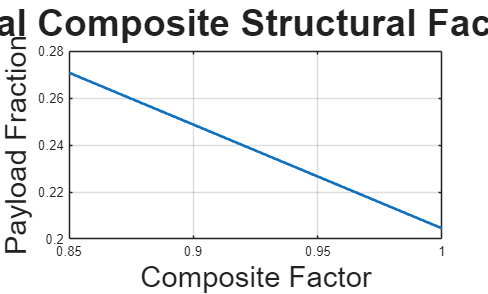


%% Composite factor trade study

% --- Sweep range ---
CompVec = 0.85:0.01:1.00;   % 15% lighter → no composite benefit

% --- Preallocate ---
OEW_vec      = zeros(size(CompVec));
Fuel_vec     = zeros(size(CompVec));
Payload_vec  = zeros(size(CompVec));
PayloadFrac  = zeros(size(CompVec));

for i = 1:length(CompVec)

    CompositeFactor = CompVec(i);

    %% --- OEW ---
    A = 0.97; 
    C = -0.06;
    OEWfrac = A * MTOW_est^C;
    OEW = OEWfrac * MTOW_est * CompositeFactor;

    %% --- Mission Inputs ---
    E_hr = 0.75;   
    M = 0.86;   
    LDmax = 16.1/0.886;

    fw = 0.970; 
    fc = 0.985; 
    fl = 0.995; 
    K  = 1.06;

    Ccr_hr = 0.50; 
    Clo_hr = 0.40; 
    eta = 0.90;

    Ccr_hr = eta*Ccr_hr;  
    Clo_hr = eta*Clo_hr;

    a_ms = 295;                 
    V_ms = M*a_ms;              
    R_m  = Rreq*1000;           

    LDcr = 0.866*LDmax;

    %% --- Mission Fractions ---
    fcr = exp(-(R_m)*(Ccr_hr/3600)/(V_ms*LDcr));
    flo = exp(-(E_hr*3600)*(Clo_hr/3600)/(LDmax));

    WendW0 = fw*fc*fcr*flo*fl;
    FuelFrac = K*(1 - WendW0);
    Fuel = FuelFrac*MTOW_est;

    %% --- Payload ---
    Payload = MTOW_est - OEW - Fuel;

    %% --- Store ---
    OEW_vec(i) = OEW;
    Fuel_vec(i) = Fuel;
    Payload_vec(i) = Payload;
    PayloadFrac(i) = Payload/MTOW_est;

end

figure
plot(CompVec, PayloadFrac,'LineWidth',2)
grid on
xlabel('Composite Factor',fontsize=22)
ylabel('Payload Fraction',fontsize=22)
title('Unconventional Composite Structural Factor Trade Study',fontsize=28)